% Package orientation: Dedicated held-out test for a separately trained SPSA network.

% TEST_SPSA_GPU_implementation_dynamical_systems_vanderpol.mlx
% Load SPSA-trained Van der Pol networks and evaluate them with the same
% closed-loop test, plots, diagnostics, and publication-data export used by
% the main GPU dynamics test script. This script does not train.

clear; clc;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);
clear snn_plot_dynamics_test_trajectories snn_plot_dynamics_sections_and_return_maps plot_closed_loop_validation_trajectories;

%% ---------------- Saved SPSA Network ----------------
% The SPSA runner currently creates seed 1 by default. Use [1 2 3] after
% training all three SPSA seeds to obtain multi-seed release statistics.
test_seeds = [1];
diagnostic_seed_index = 1;
test_backend = 'gpu';
[model_files, model_file] = snn_resolve_spsa_model_files( ...
    repo_root, 'dynamical_systems_vanderpol', test_seeds, diagnostic_seed_index);
save_diagnostic_files = false;
diag_dir = fullfile(repo_root, 'outputs', 'diagnostics', 'dynamical_systems_vanderpol_spsa_test_gpu_primary');
if save_diagnostic_files && exist(diag_dir, 'dir') ~= 7, mkdir(diag_dir); end

%% ---------------- Evaluation Overrides ----------------
closed_loop_test_time = single(50); % Duration of the scored comparison interval.
closed_loop_test_warmup_time = single(5); % Network-only autonomous warmup before truth is initialized from its terminal state.
closed_loop_test_ics = 5;
closed_loop_test_ic_seed = 123;
min_peak_prominence = 1;

opts = struct();
opts.model_files = model_files;
opts.seed_list = test_seeds;
opts.model_file = model_file;
opts.closed_loop_test_time = closed_loop_test_time;
opts.closed_loop_test_warmup_time = closed_loop_test_warmup_time;
opts.closed_loop_test_ics = closed_loop_test_ics;
opts.closed_loop_test_ic_seed = closed_loop_test_ic_seed;

%% ---------------- Run Closed-Loop Test ----------------
result = snn_primary_api('test_dynamics', 'dynamical_systems', test_backend, opts);

[SEED AUDIT] Single seed tested; no pairwise network-difference check required.
Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\dynamical_systems_vanderpol_spsa_gpu_test_analysis_20260721_145540_309.mat


fprintf('Tested SPSA-trained Van der Pol network(s) for seed(s) [%s] with the GPU test backend.\n', num2str(test_seeds));

Tested SPSA-trained Van der Pol network(s) for seed(s) [1] with the GPU test backend.


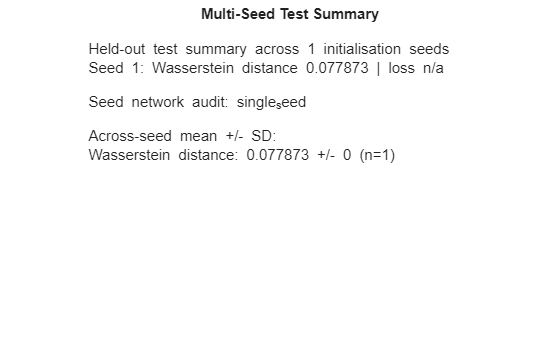

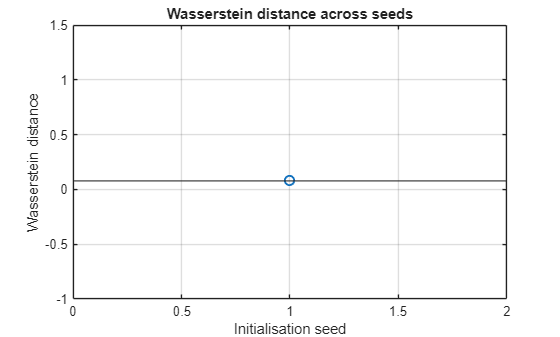

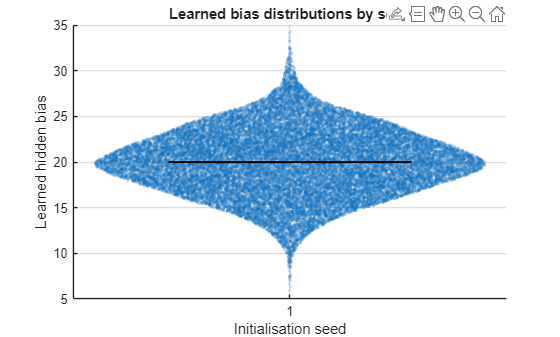

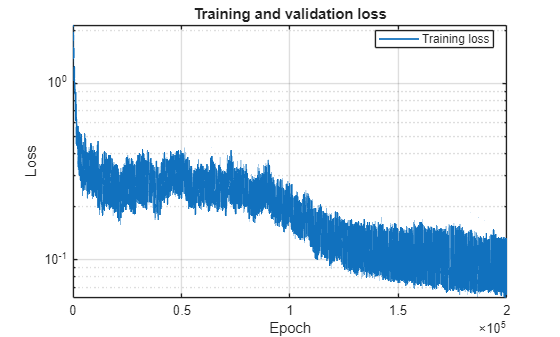

snn_plot_test_result(result);

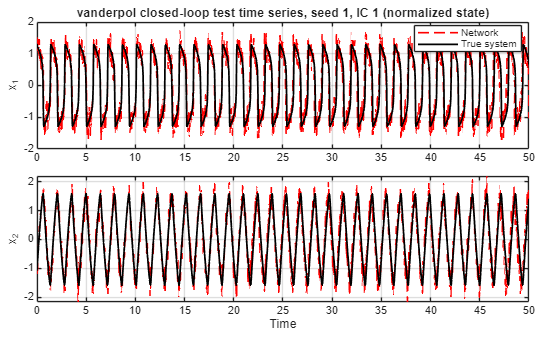

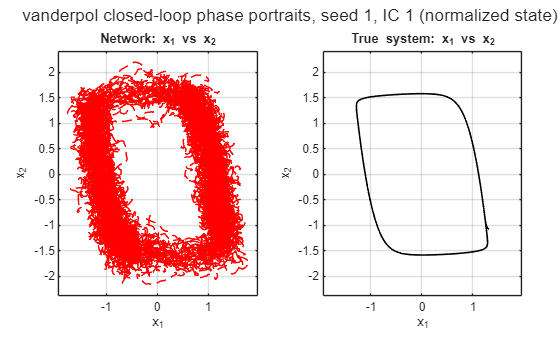

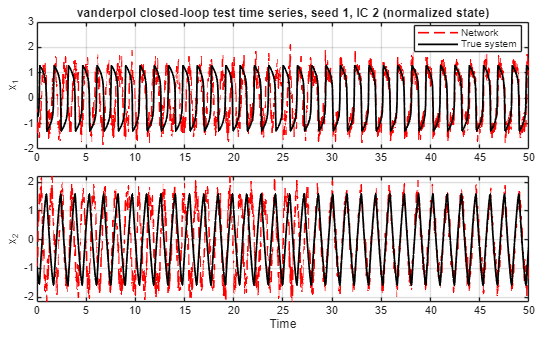

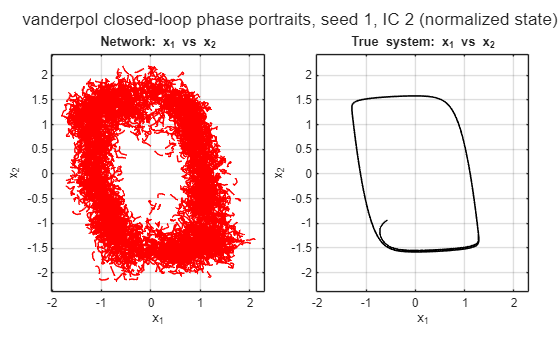

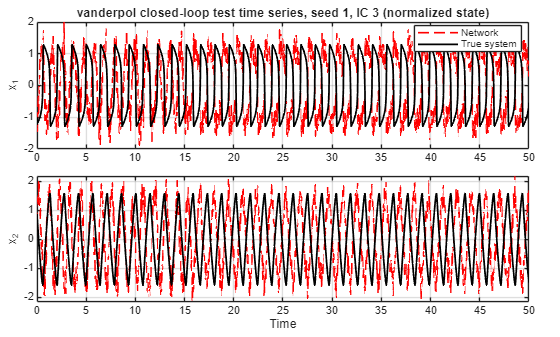

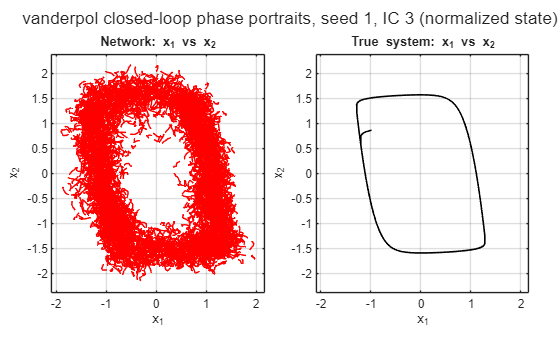

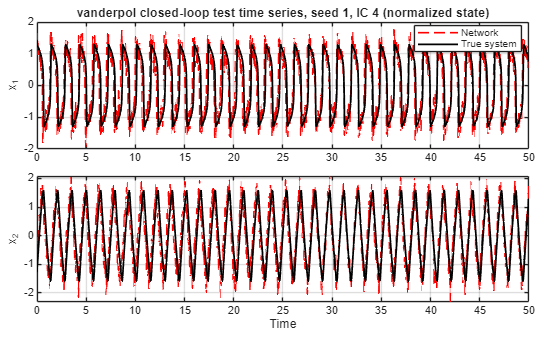

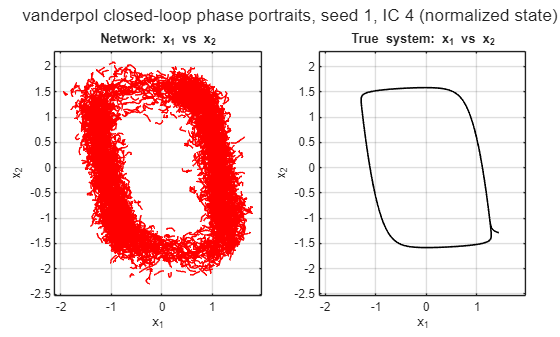

snn_plot_dynamics_test_trajectories(result);

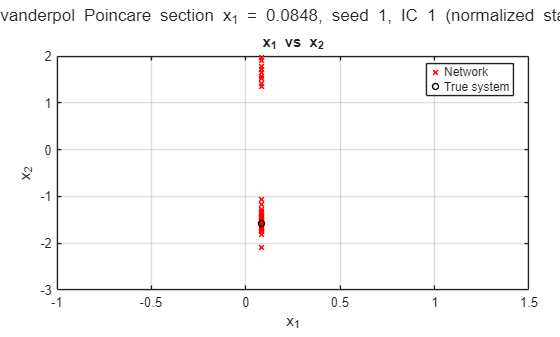

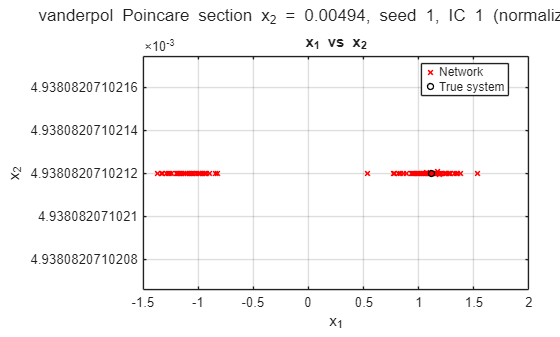

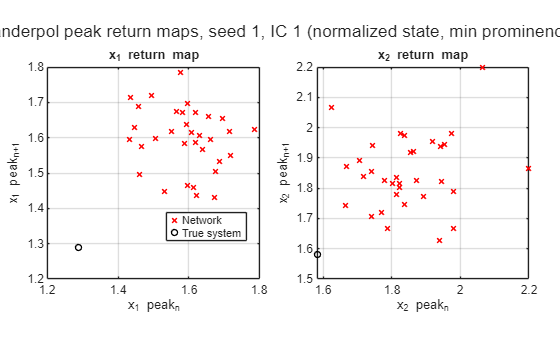

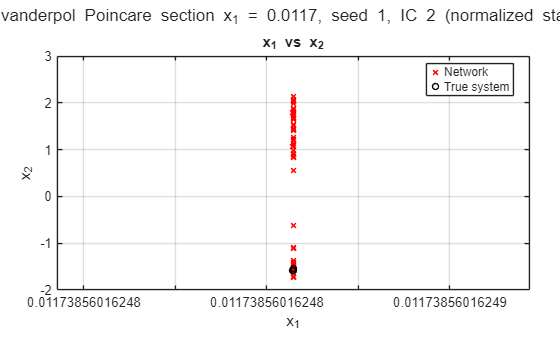

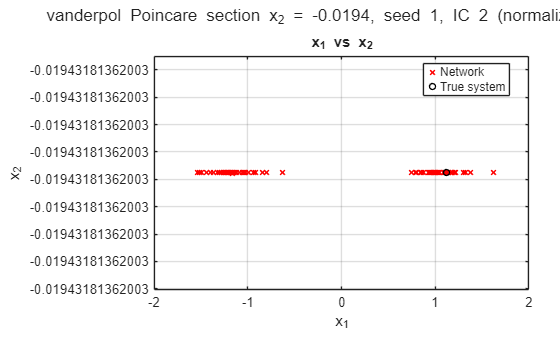

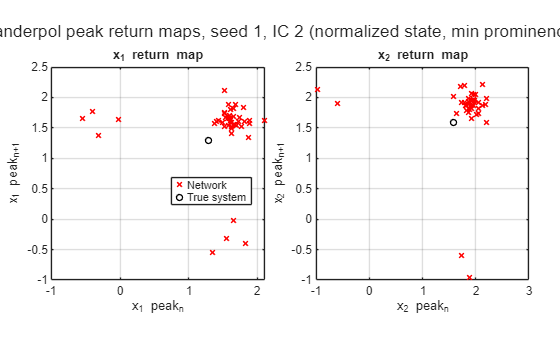

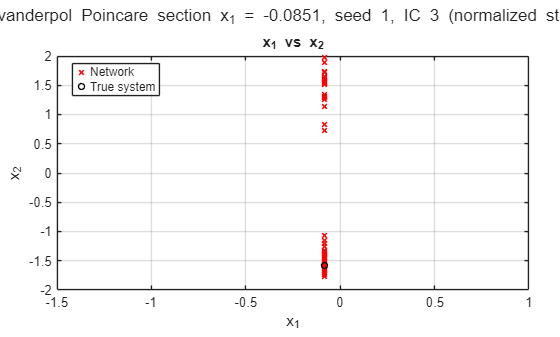

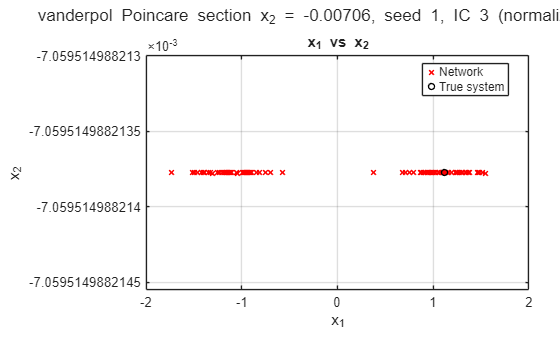

snn_plot_dynamics_sections_and_return_maps(result, '', min_peak_prominence);


=== Spiking Diagnostics: vanderpol_test_dynamics ===
Samples: 1 | Neurons: 32000 | Steps/sample: 5000 | Seconds/sample: 5
Mean neuron firing rate: 1.60946 Hz | median 0 Hz | 95th percentile 7 Hz
Active neurons: 15514 / 32000 (48.48%)
Silent neurons: 16486 / 32000 (51.52%)
Mean population rate by sample: 1.60946 Hz/neuron
Mean active neurons by sample: 48.48% | silent 51.52%
Total within-sample ISIs counted: 241999
Median per-neuron mean inverse-ISI rate: 5.82333 Hz


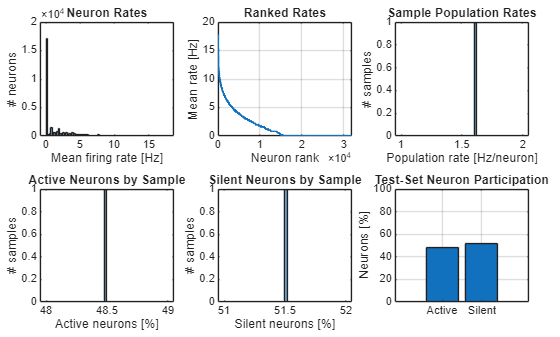

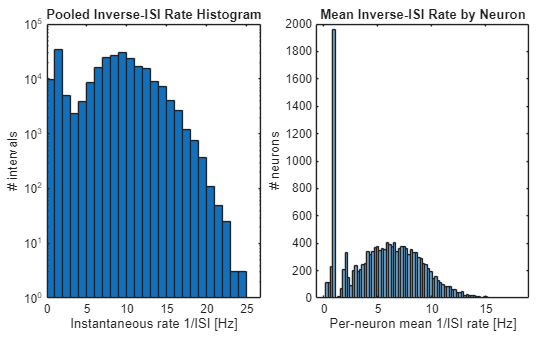

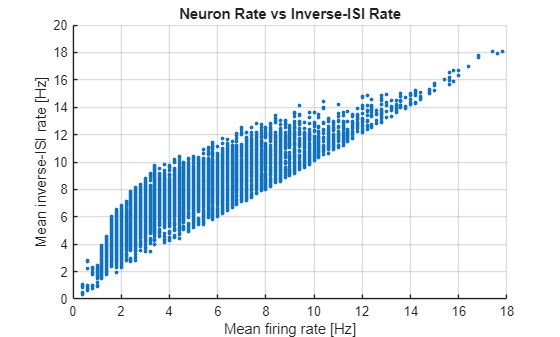

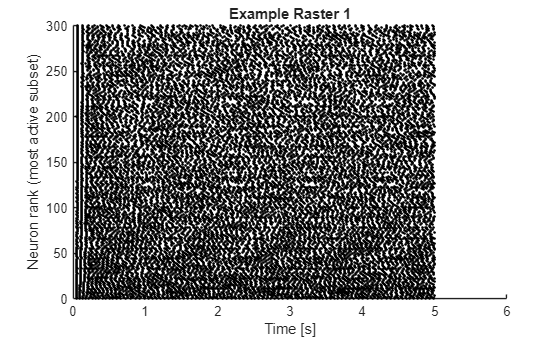

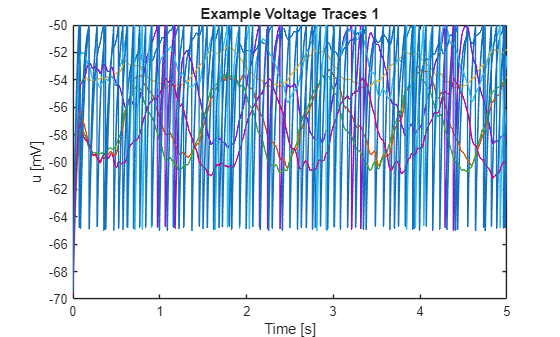

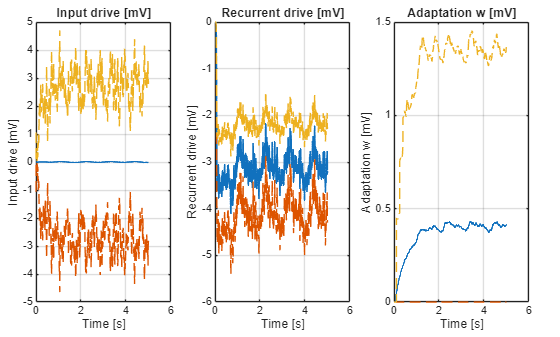

[SPIKING] Displayed spiking diagnostics without saving files. To save files, pass 'save_files', true.



%% ---------------- Spiking Dynamics Diagnostics ----------------
diag_opts = struct();
diag_opts.model_file = model_file;
diag_opts.output_dir = diag_dir;
diag_opts.save_files = save_diagnostic_files;
diag_opts.max_samples = 8;
diag = snn_primary_api('spike_diagnostics_dynamics', 'dynamical_systems', 'cpu', diag_opts);

fprintf('Test spiking active neurons: %.2f%%%% (%d/%d); silent neurons: %.2f%%%% (%d/%d).\n', ...
    diag.active_neuron_percent, diag.active_neuron_count, diag.n_neurons, ...
    diag.silent_neuron_percent, diag.silent_neuron_count, diag.n_neurons);

Test spiking active neurons: 48.48%% (15514/32000); silent neurons: 51.52%% (16486/32000).


fprintf('Mean per-sample active neurons: %.2f%%%%; silent neurons: %.2f%%%%.\n', ...
    mean(diag.active_percent_by_sample), mean(diag.silent_percent_by_sample));

Mean per-sample active neurons: 48.48%%; silent neurons: 51.52%%.


fprintf('Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.\n');

Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.


disp(result.test);

                wasserstein_distance: 0.0779
          wasserstein_distance_by_ic: [5×1 single]
                             x0_list: [2×5 single]
                  test_x0_norm_by_ic: {5×1 cell}
              truth_diagnostic_by_ic: {5×1 cell}
       truth_simulation_failed_by_ic: [5×1 logical]
                 closed_loop_ic_seed: 123
            closed_loop_test_ic_seed: 123
               closed_loop_ic_jitter: 0.0100
             closed_loop_warmup_time: 5
               closed_loop_test_time: 50
            closed_loop_warmup_steps: 5000
    closed_loop_truth_initialization: 'network_terminal_warmup_state'
                           pred_norm: [50000×2 single]
                           true_norm: [50000×2 single]
                     pred_norm_by_ic: {5×1 cell}
                     true_norm_by_ic: {5×1 cell}
                n_initial_conditions: 5
                            gpu_bias: [32000×1 single]

